# Demographics, Stimulus

*Please contact Ted (huppert1@pitt.edu) or Hendrik (hes73@pitt.edu) to request more demos, suggestions, feedback, etc. We will update this script as needed. *

## 2.1 Demographics

### 2.1.1 Adding demographics from excel file

This example show how to add demographic frome an Excel file to raw data. 

clear all
clc
load('AnalyzIR_Dataset1.mat');

demo = readtable('AnalyzIR_Demographic1.xlsx');

job=nirs.modules.AddDemographics;
job.allowMissing = true;
job.demoTable=demo;
job.varToMatch='subject';
raw=job.run(raw);

nirs.createDemographicsTable(raw)

ans = 68×8 table
    group     subject    AgeMonths     Sex     HeadSize    ADHD    Risk     Score
    ______    _______    _________    _____    ________    ____    _____    _____

    {'G1'}    {'S11'}       14        {'M'}       43         7     {'A'}      1  
    {'G1'}    {'S12'}       14        {'M'}       45         8     {'B'}      6  
    {'G1'}    {'S13'}       30        {'F'}       42         7     {'C'}      5  
    {'G1'}    {'S15'}       13        {'M'}       45         9     {'C'}      6  
    {'G1'}    {'S17'}       36        {'F'}       44         8     {'B'}      4  
    {'G1'}    {'S19'}       29        {'F'}       44         1     {'B'}      3  
    {'G1'}    {'S22'}       25        {'M'}       43  

### 2.1.2 Adding demographics manually

This example show how to add demographic information manually

raw(1).demographics

ans = Dictionary Class Containing:
     group  :  G1
     subject  :  S11
     AgeMonths  :  14
     Sex  :  M
     HeadSize  :  43
     ADHD  :  7
     Risk  :  A
     Score  :  1

raw(1).demographics('ClinicalScore') = 10;
raw(1).demographics('Covariates') = 'population1';
raw(1).demographics

ans = Dictionary Class Containing:
     group  :  G1
     subject  :  S11
     AgeMonths  :  14
     Sex  :  M
     HeadSize  :  43
     ADHD  :  7
     Risk  :  A
     Score  :  1
     ClinicalScore  :  10
     Covariates  :  population1

### 2.1.3 Modify demographics

This example show how to modify Score demographics (between 1-6) to Low (1-2), Medium (3-4), and High (5-6)

tblDemo = nirs.createDemographicsTable(raw);
for i = 1:length(raw)
    if tblDemo.Score(i) <= 2
        raw(i).demographics('ScoreEdit') = 'Low';
    elseif tblDemo.Score(i) >= 5
        raw(i).demographics('ScoreEdit') = 'High';
    else
        raw(i).demographics('ScoreEdit') = 'Medium';
    end
end
nirs.createDemographicsTable(raw)

ans = 68×11 table
    group     subject    AgeMonths     Sex     HeadSize    ADHD    Risk     Score    ClinicalScore      Covariates       ScoreEdit 
    ______    _______    _________    _____    ________    ____    _____    _____    _____________    _______________    __________

    {'G1'}    {'S11'}       14        {'M'}       43         7     {'A'}      1            10         {'population1'}    {'Low'   }
    {'G1'}    {'S12'}       14        {'M'}       45         8     {'B'}      6           NaN         {0×0 char     }    {'High'  }
    {'G1'}    {'S13'}       30        {'F'}       42         7     {'C'}      5

## 2.2 Stimulus Events

### 2.2.1 Rename stimulus events

This example show how to rename stimulus events 'A' and 'B' to 'TaskA', and 'TaskB'

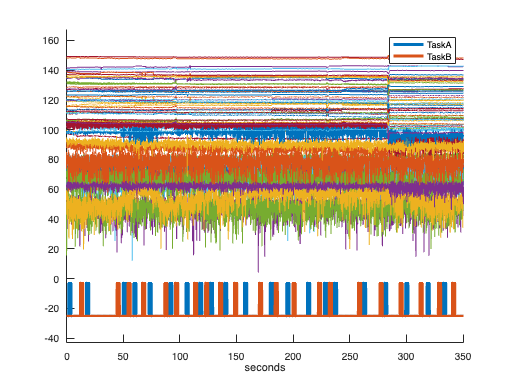

job = nirs.modules.RenameStims();
job.listOfChanges = {'A',  'TaskA'; 'B', 'TaskB'};
raw = job.run(raw);
figure; raw(1).draw

### 2.2.2 Edit stimulus events

This example show how to change duration (TaskA and TaskB has 2-s), change to 4-s

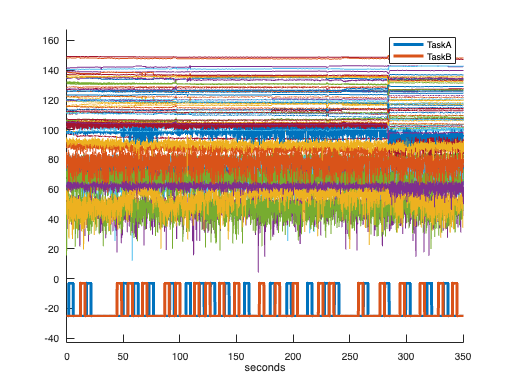

for i = 1:length(raw)
    stimA = nirs.design.StimulusEvents;
    stimA.name = 'TaskA';
    stimA.onset = raw(i).stimulus('TaskA').onset;
    stimA.amp = ones(21,1);
    stimA.dur = ones(21,1)*4;
    raw(i).stimulus('TaskA') = stimA;
    
    stimB = nirs.design.StimulusEvents;
    stimB.name = 'TaskB';
    stimB.onset = raw(i).stimulus('TaskB').onset;
    stimB.amp = ones(21,1);
    stimB.dur = ones(21,1)*4;
    raw(i).stimulus('TaskB') = stimB;
end
figure; raw(1).draw


%Another alternative, we can automatically change all duration to 3-s
raw = nirs.design.change_stimulus_duration(raw, 'TaskA', 3);
raw = nirs.design.change_stimulus_duration(raw, 'TaskB', 3);

### 2.2.3 Adding stimulus events

This example show how to add stimulus events

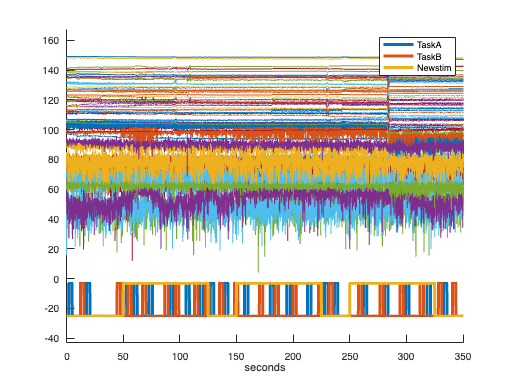

stim = nirs.design.StimulusEvents;
stim.name = 'TaskC';
stim.onset = [50 150 250];
stim.amp = ones(3,1);
stim.dur = ones(3,1)*75;
raw(1).stimulus('Newstim') = stim; 
figure; raw(1).draw

### 2.2.3 Keep stimulus

This example show how to Keep stimulus

job = nirs.modules.KeepStims();
job.listOfStims = {'TaskA', 'TaskB'};
raw = job.run(raw);
figure; raw(1).draw